# Quadcopter PID Control - Altitude

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In this script, let's learn the concepts behind how a quadcopter control system works, and run some simple simulations to illustrate as we go along. We will consider only one degree of freedom (vertical hover control) and idealized propellers without detailed electrical modeling. This script and models are built on the content from [QuadcopterMovement](matlab:open('.\QuadcopterMovement.mlx')). 

For simplicity, we will assume a rigid-body dynamic model and assume that all propellers produce unidirectional thrust perpendicular to the quadcopter system.  

**Note:** If you are new to PID Control Tuning, please consider completing the [Control Design Onramp with Simulink](https://matlabacademy.mathworks.com/details/control-design-onramp-with-simulink/controls) online course before continuing, so the concepts are clear. You may want to go deeper into controls with the Tech Talks, courses, and example linked in Further Resources.

## Loading up Quadcopter Parameters

clear kT quad_m
load x_quad_params.mat kT quad_m W M g

## Equation of Motion (1D)

For a purely vertical motion in the $z$ direction, neglecting drag forces (as the velocities are small), the equation of motion can be written as:


$$m\ddot{z} = mg - f_{\text{prop}} $$


where $m$ is the mass of the quadcopter, $g$ is the acceleration due to gravity, and $f_{\text{prop}}$ is the thrust force from the propellers. Recall that we know how to solve this equation from the earlier exercises on [Projectile Motion](matlab:open('./ProjectileMotion.mlx')).

The gravitational force (weight) will remain constant. Therefore, we only need to adjust the propeller forces to reach a given altitude. 

### Modeling Propeller Forces 

Recall that for an x-configuration quadcopter, the total thrust force can be computed as follows:

$f_{\text{prop}} = k_{\text{T}}\left(N_1^2 + N_2^2 + N_3^2 + N_4^2\right)$, 

where $k_{\text{T}}\propto \rho r^4$, as described in [Propeller Model](matlab:open('./PropellerModel.mlx')) and [QuadcopterBasics](matlab:open('.\QuadcopterBasics.mlx')), and $N_i$ is the angular speed of the $i^{\text{th}}$ propeller in rotations per minute.

Assuming perfect vertical motion and setting all propeller speeds the same,

$N_1 = N_2 = N_3 = N_4 = N$,

we get

$f_{\text{prop}} = 4k_{\text{T}}N^2$.

#### Propeller Thrust vs Speed

The performance curves of the propellers are plotted in the following code:

 
N = 0:1000:10000; % sweeping speed values from 0 - 10,000 rpm
plot(N, kT * N.^2)
xlabel('Speed (rpm)')
ylabel('Thrust (N)')
grid minor

We can model this using block diagrams for convenience, as shown below. When developing a controller, the propeller speed can be fed as an input.

$f_{\text{prop}} = 4k_T\left(4000\right)^2$ is represented as:

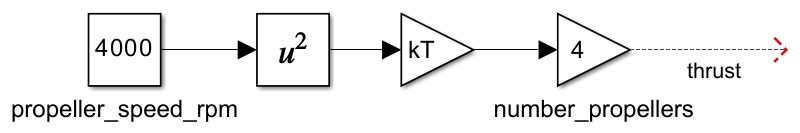

Then, using $F = Ma = M\ddot{z}$ at a slightly higher rotational speed, the plant model looks as follows:

$\displaystyle z = \int \!\!\!\!\!\int \frac{Mg-4k_T\left(4500\right)^2}{M}\; dt \, dt$     which is

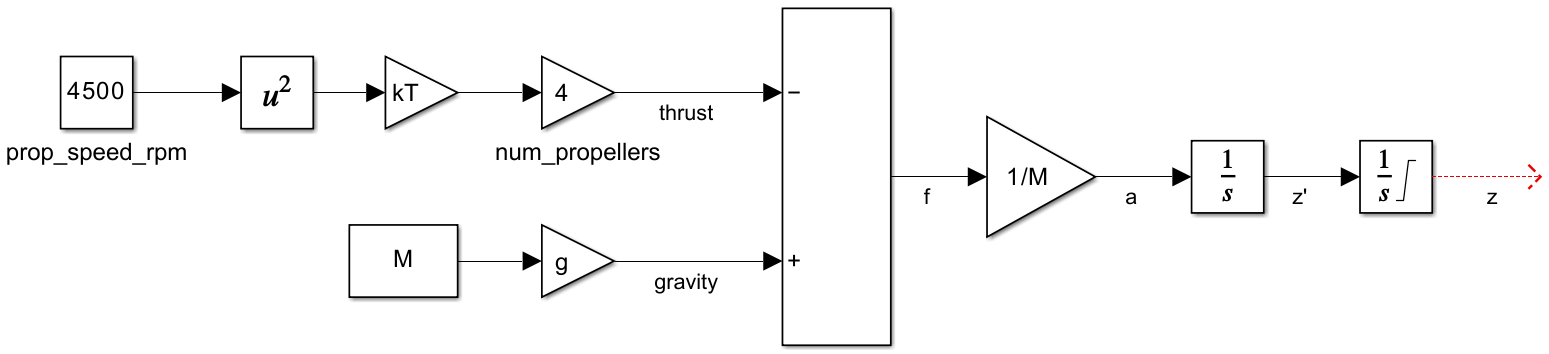

## Closed-Loop Feedback Control

To ensure we have a robust solution, it is advisable to use feedback control. A simple model is linked below using PID control.

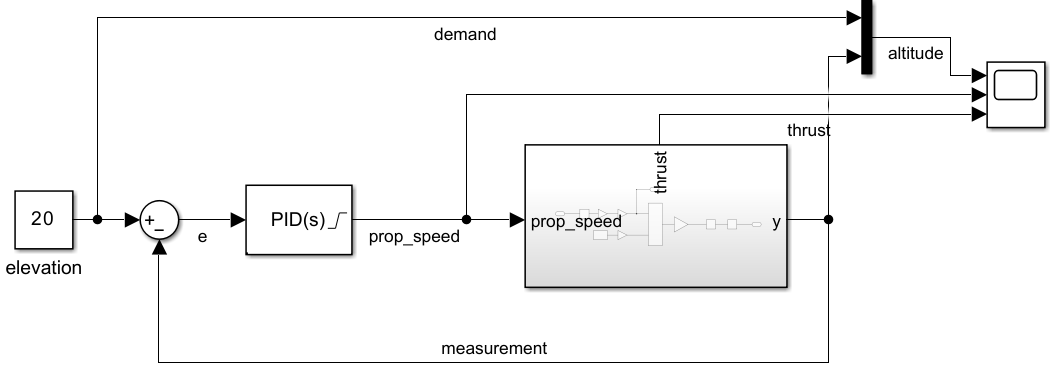

For testing purposes, we can start the quadcopter from the ground and have it reach a set altitude (e.g., 20m). To work with positive altitudes, note that we have reversed the orientation of our axes such that $\ddot{z} = 4k_TN^2-Mg$.

open("QuadcopterPID_Vertical.slx");

 **Exercise. **Add a PID controller block (Simulink/Continuous). The input signal to the PID Controller is the error signal, `e`, out of the sum block. The output signal from the PID controller is the propeller speed signal, `prop_speed`.

### **Demonstration:** Tuning the PID Controller

As the plant model is non-linear, it can be a little challenging to obtain a good controller model. However, it is possible to attain the required altitude setpoint with some experimentation. 

  **Try**. Open the block parameters for the PID Controller block: 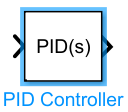

  **Try**. First, set the initial rotational speed to 4000 rpm, as that is the known design point. To do this, open the **Initialization** tab and set the Integrator value to 4000. Don't forget to click Apply. It will be easier for the controller to converge from that point.

The Proportional (P), Integral (I), and Derivative (D) values can be set in the **Main** tab. After you try each combination of values, run the model and observe the results in the Scope. 

#### Proportional

When using purely 'Proportional' control, we can achieve the required altitude, but the response is extremely oscillatory.

  **Try**. P = 80, I = 0, D = 0

#### Derivative

Using a P-D Controller, we can reduce the oscillations, but the response is still slow.

  **Try**. P = 120, I = 0, D = 40

#### PID

What happens if we use all three values?

  **Try**. P = 200, I = 50, D = 150.

#### PID - Anti-windup + Saturation

By using [anti-windup methods](https://www.mathworks.com/help/simulink/slref/anti-windup-control-using-a-pid-controller.html) and output saturation, we can prevent the output from overshooting. In the **Saturation** tab, click Limit output to enable other options. Then set the following:

The saturation limits communicate the design specification that acceptable rotation speeds are from 0 to 10,000 rpm. Together with the PID values below, this controller stabilizes the drone at a given altitude in just a few seconds.

  **Try**. P = 200, I = 50, D = 150. Filter Coefficient = 10

## **Quadcopter Hover Control**

Once we have a basic PID controller in place, we can use the controller to implement **altitude hover control**. Note that once we change the model, the PID controller gains may need additional tuning to achieve acceptable performance. We should be able to reach a state where we specify a hover altitude and the drone responds within a couple of seconds. 

  **Try**. Open the model, add a PID Controller, set the **Saturation** and **Initialization** values suggested in the Demonstration above, and try the PID Tuner App to implement altitude hover control yourself - it is excellent practice for working with real hardware as well! There is guidance on using the PID Tuner App in the [PID Controller Techniques course](https://matlabacademy.mathworks.com/details/pid-control-techniques/otmlslpct), Automatically Tuning PID Controllers section 3.2.2.

open("UAV_Hover_Sim.slx");

##  **Quadcopter Position Control using multiple PID loops**

The hover control for the drone relies on a single PID control feedback loop to control the altitude along the z-axis. However, when working with position-control applications (in the X-Y direction), we rely on cascaded PID loops to achieve the results we need.

open("XY_Control.slx");

**Movement Commands. **These blocks set the desired values of position, orientation (yaw), and altitude for the quadcopter.

**Position Control. **A collection of three controllers: 

- altitude to compute the necessary thrust

- XY-position to compute the pitch and roll necessary to move toward the desired XY location

**Attitude Control. **Another controller that uses the information about the current state and the desired roll, pitch, and yaw, to compute values to use together with the computed thrust in setting the propeller speeds. 

Both sets of controllers must work together to move the drone to the specified point. As discussed in [Quadcopter Movement](matlab:open('.\QuadcopterMovement.mlx')), first, the quadcopter has to tilt along the appropriate axis, and then it can control the thrust to move laterally. The XY_Control.slx model closely follows the [Quadcopter_Control_Simulink model](https://www.mathworks.com/matlabcentral/fileexchange/115770-quadcopter_lessons/files/UAV_Quadcopter_Lessons/UAV_03_QuadcopterControl/SimulinkModels/Quadcopter_Control_Simulink.slx) in [1].

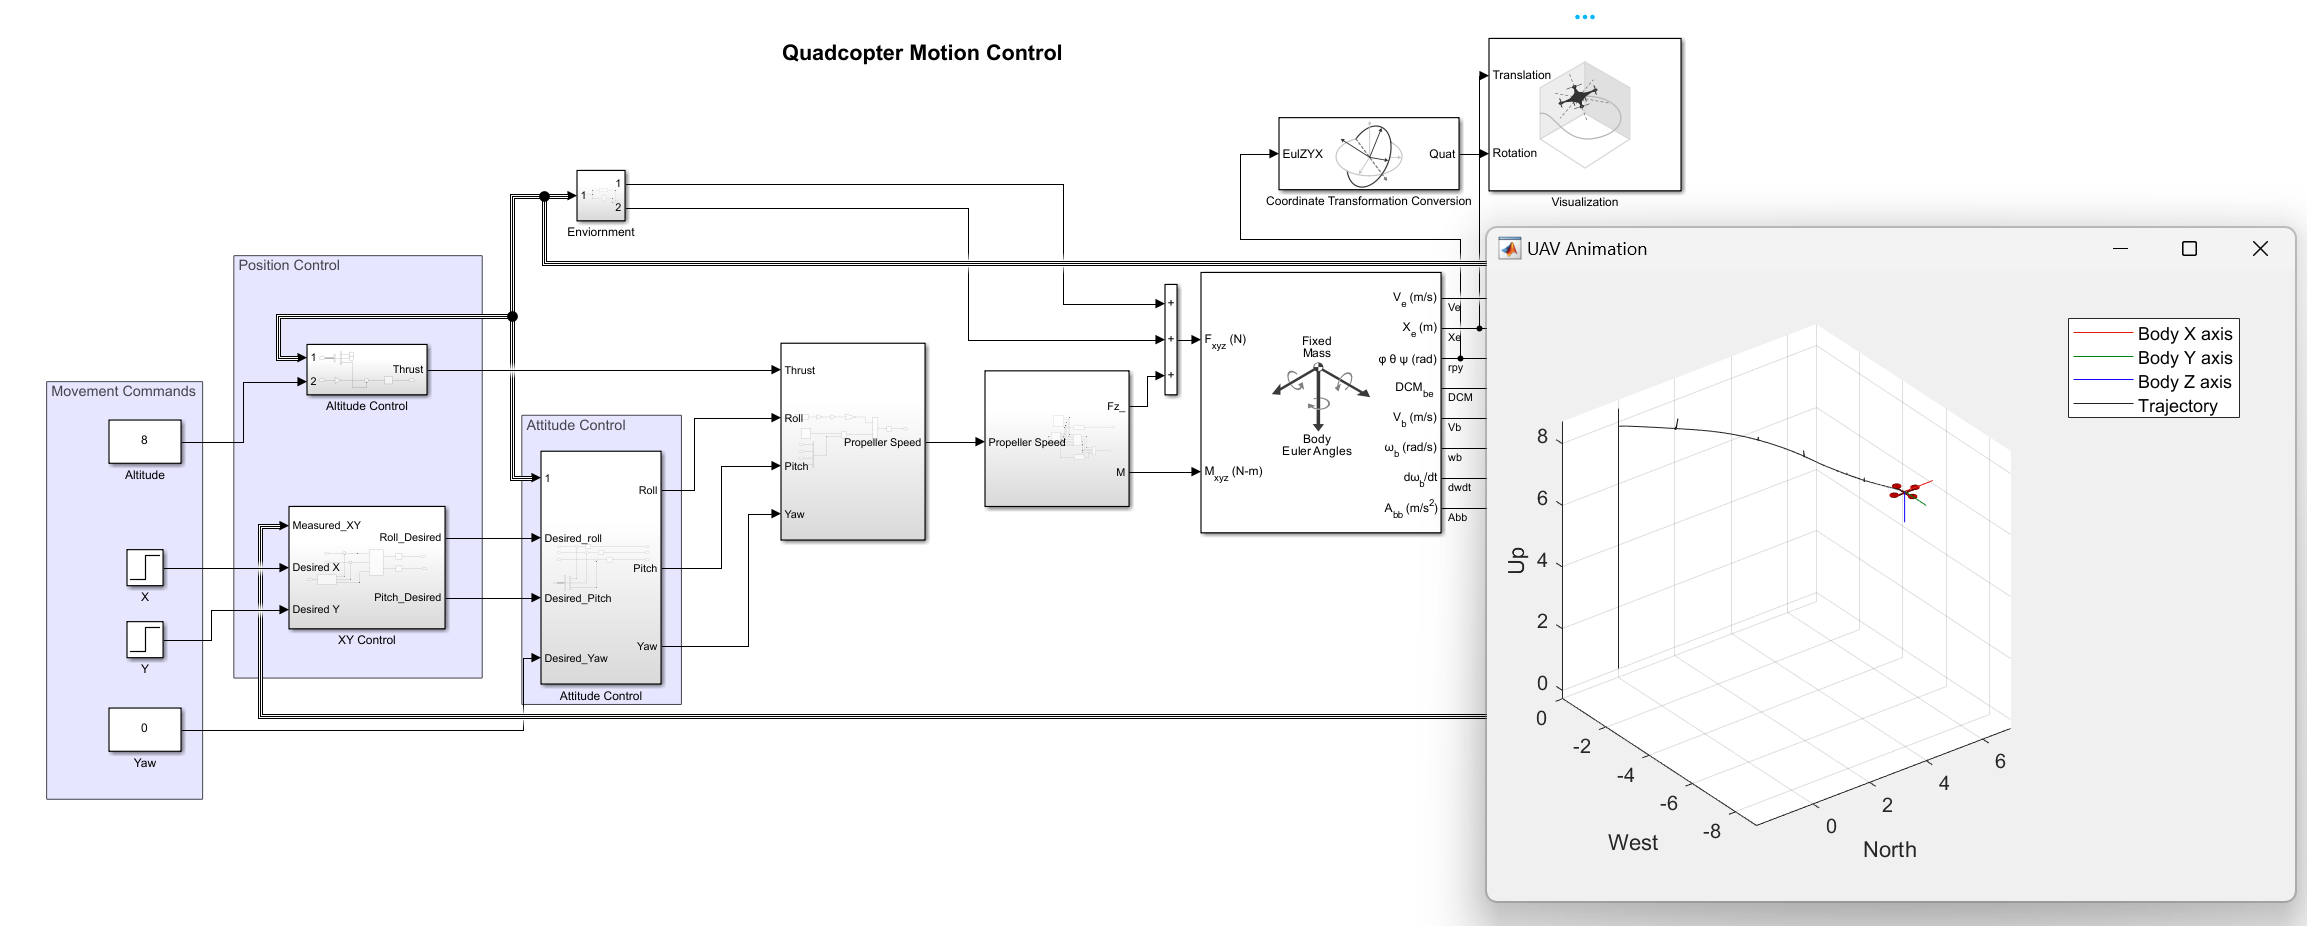  **Try**. Run the model. Then explore.

- Set a new altitude value and run the model. Observe the results in the animation and the scope.

- Change the X and Y input values and run the model. Observe the results.

- Change the yaw value and run the model. Observe the results.

 **Reflect**.

- Open the Propeller Speed subsystem. Are the computations familiar? Why or why not?

- What is the physical meaning of the signed square root?

As you explore XY_Control, you should note many instances where constants are not set in a physically realistic manner. [Multidomain Physical Modeling](matlab:open('.\MultidomainPhysicalModeling.mlx')) introduces more complex mechanical and electrical components before you get to explore a [complete quadcopter model](matlab:open('.\QuadcopterFromFEX.mlx')).

This fundamental understanding of quadcopter modeling and control provides a strong foundation for building more complex applications. Beyond the basics, engineers can optimize design parameters, plan movement trajectories, and optimize payload deliveries, aiming to achieve increasingly higher levels of autonomy through advanced sensing and perception. The rest of this course explores a few of the above aspects at an introductory level, and more resources are provided for further exploration.

## Further Resources

Watch Tech Talk videos on control design, including [Understanding PID Control](https://www.mathworks.com/videos/series/understanding-pid-control.html).

- [Control Systems Video Series](https://www.mathworks.com/videos/tech-talks/controls.html)

Learn more about designing and tuning PID controllers in Simulink.

-  [PID Control Techniques](https://matlabacademy.mathworks.com/details/pid-control-techniques/otmlslpct)

Or dive deeper with a 5 course learning path on control design. 

-  [Control System Design with MATLAB and Simulink](https://matlabacademy.mathworks.com/details/control-system-design-with-matlab-and-simulink/lpmlslcsd) 

The following example shows how to tune PID Controllers used in the attitude and position control of a small quadcopter in only one simulation using the Closed-Loop PID Autotuner block.

- [PID Autotuning for UAV Quadcopter](https://www.mathworks.com/help/slcontrol/ug/pid-controller-tuning-for-a-uav-quadcopter.html) 

## Citations

[1] Michael Thorburn (2026). Quadcopter_Lessons (https://github.com/mathorburn/Quadcopter_Lessons/releases/tag/v0.1.2), GitHub. Retrieved February 27, 2026. 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))